fprintf("PLEASE SELECT AN IMAGE\n")

PLEASE SELECT AN IMAGE


i=uigetfile('*.*');
j=imread(i)

j = 408×612×3 uint8 array
j(:,:,1) =

   251   250   250   249   249   248   248   247   249   249   248   247   245   242   240   239   241   234   227   223   223   223   219   215   223   213   205   207   214   219   219   216   217   204   200   211   223   225   224   225   226   225   224   223   225   228   231   233   226   229   233   234   234   233   234   235   233   235   237   236   234   232   232   233   236   237   237   237   236   232   230   228   222   202   193   204   213   210   206   210   201   199   196   195   198   204   210   215   222   225   229   232   232   233   237   240   237   238   238   239   240   241   242   242   249   247   247   248   251   251   247   243   247   244   239   239   239   242   244   243   229   238   243   241   230   221   218   220   209   210   211   214   219   222   226   228   239   240   241   243   245   246   249   248   251   251   250   249   249   250   251   251   254   254   254   254   254   254   254   254  

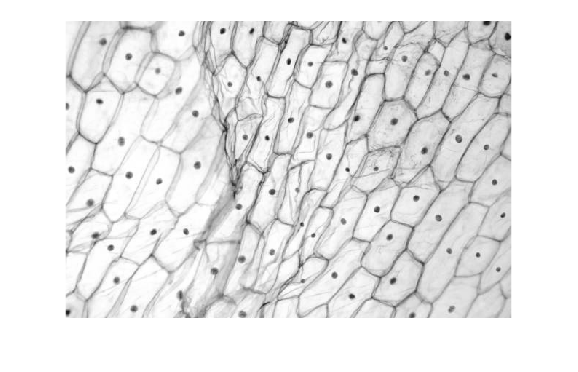

k=rgb2gray(j);
imshow(k)

[r,c]=size(k)

r = 408

c = 612

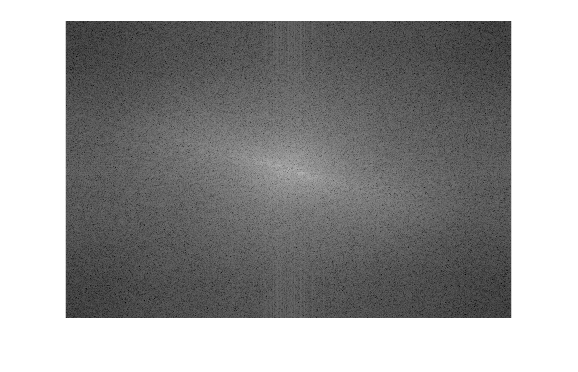

l=fft2(k);
m=fftshift(l);
n=abs(m);
o=log(1+n);
imshow(o,[]);

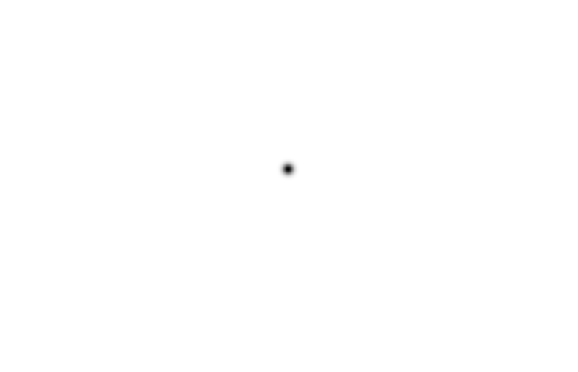

Z=zeros(r,c);
d0=5;
for R=1:r
    for C=1:c
        d=sqrt((R-(r/2))^2+(C-(c/2))^2);
        Z(R,C)=1-exp(-(d^2)/(2*(d0)^2));
    end
end


imshow(Z)

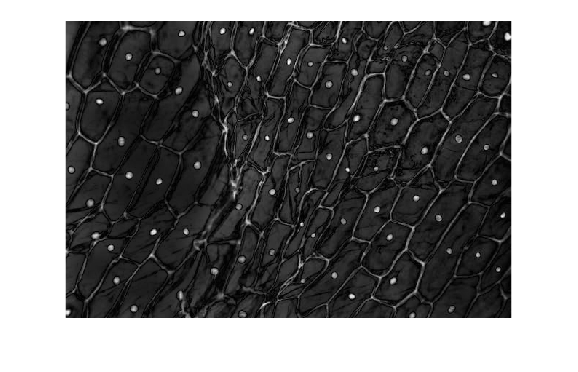

new=m.*Z;
new1=fftshift(new);
new2=ifft2(new1);
imshow(abs(new2),[]);

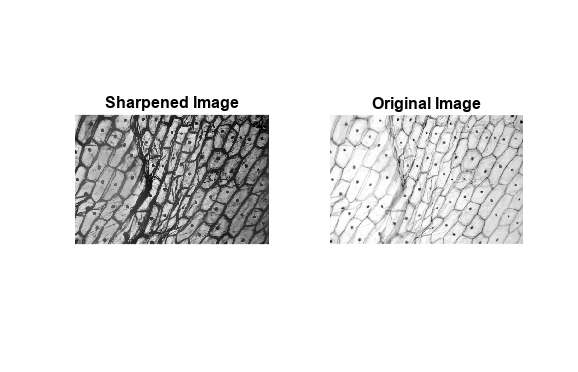

edge=abs(new2);
sharp=double(k)+edge;
subplot(1,2,1); imshow(sharp,[]); title('Sharpened Image');

subplot(1,2,2); imshow(k,[]); title('Original Image');